# Chap 4 - Embeddings

Resource: [A Tale of Two Cities by Charles Dickens | Project Gutenberg](https://www.gutenberg.org/ebooks/98)

% Define the paragraph as a string literal using concatenation for readability
paragraph = "It was the best of times, it was the worst of times, " + ...
    "it was the age of wisdom, it was the age of foolishness, " + ...
    "it was the epoch of belief, it was the epoch of incredulity, " + ...
    "it was the season of Light, it was the season of Darkness, " + ...
    "it was the spring of hope, it was the winter of despair, " + ...
    "we had everything before us, we had nothing before us, " + ...
    "we were all going direct to Heaven, we were all going direct the other way " + ...
    "- in short, the period was so far like the present period, " + ...
    "that some of its noisiest authorities insisted on its being received, " + ...
    "for good or for evil, in the superlative degree of comparison only.";

% Split the paragraph into sentences using ", " as the delimiter
sentences = split(paragraph, ", ");

% Select the first sentence (MATLAB indexing starts at 1)
sentence1 = sentences(1)

sentence1 = "It was the best of times"

### OpenAI embedding service

emb = extractOpenAIEmbeddings(sentence1)

emb =     0.0100   -0.0019    0.0083   -0.0402   -0.0179    0.0026   -0.0008   -0.0045   -0.0127   -0.0410    0.0035    0.0257    0.0134   -0.0020    0.0047    0.0106    0.0423    0.0003   -0.0036   -0.0005   -0.0047    0.0214    0.0023   -0.0077   -0.0109    0.0012    0.0026   -0.0274    0.0306   -0.0002   -0.0005   -0.0038   -0.0222   -0.0073   -0.0333   -0.0561   -0.0322   -0.0087    0.0070    0.0050    0.0131   -0.0067   -0.0031    0.0237   -0.0276    0.0074    0.0137    0.0051   -0.0172    0.0015


size(emb)

ans =            1        1536


embs = extractOpenAIEmbeddings(sentences)

embs =     0.0100   -0.0019    0.0083   -0.0402   -0.0179    0.0026   -0.0008   -0.0045   -0.0127   -0.0410    0.0035    0.0257    0.0134   -0.0020    0.0047    0.0106    0.0423    0.0003   -0.0036   -0.0005   -0.0047    0.0214    0.0023   -0.0077   -0.0109    0.0012    0.0026   -0.0274    0.0306   -0.0002   -0.0005   -0.0038   -0.0222   -0.0073   -0.0333   -0.0561   -0.0322   -0.0087    0.0070    0.0050    0.0131   -0.0067   -0.0031    0.0237   -0.0276    0.0074    0.0137    0.0051   -0.0172    0.0015
   -0.0169    0.0028    0.0003   -0.0268   -0.0102    0.0076   -0.0040   -0.0052   -0.0151   -0.0424    0.0038    0.0312    0.0170    0.0168   -0.0017    0.0100    0.0420    0.0116    0.0040    0.0043    0.0018    0.0244   -0.0022    0.0017   -0.0106   -0.0002    0.0091   -0.0296    0.0303   -0.0143   -0.0144   -0.0099   -0.0159   -0.0165   -0.0405   -0.0398   -0.0019   -0.0112    0.0035   -0.0126    0.0120   -0.0123    0.0014    0.0238   -0.0453    0.0028   -0.0000   -0.0136   -0.0255  

### Semantic similarity

Since the norm of the vector embeddings is 1, cosine similarity between the vectors results in a simple dot product.

norm(emb)

ans = 1.0000

dot(embs(1,:),embs(2,:))

ans = 0.9032

sentences(1),sentences(2)

ans = "It was the best of times"

ans = "it was the worst of times"

### Open-source embedding model

model = documentEmbedding(Model='all-MiniLM-L6-v2'); % or 'all-MiniLM-L12-v2'
embedding1 = model.embed(sentence1)

embedding1 =    -0.0452    0.0716    0.0172   -0.0316    0.0476   -0.0080    0.0121    0.0578   -0.0236    0.0006   -0.0058    0.1645    0.0872    0.0575   -0.0096    0.0257    0.0318    0.0048   -0.0224   -0.0381   -0.0567   -0.0271    0.0124    0.0493    0.0092    0.0300    0.0072    0.0636   -0.0289    0.0344   -0.0391   -0.0202    0.0009    0.0116   -0.0567    0.0033    0.0108   -0.0678    0.0246   -0.0009    0.0038   -0.0342   -0.0243   -0.0845    0.0169    0.0033    0.0806   -0.0888    0.0559    0.0244


### Plotting embeddings

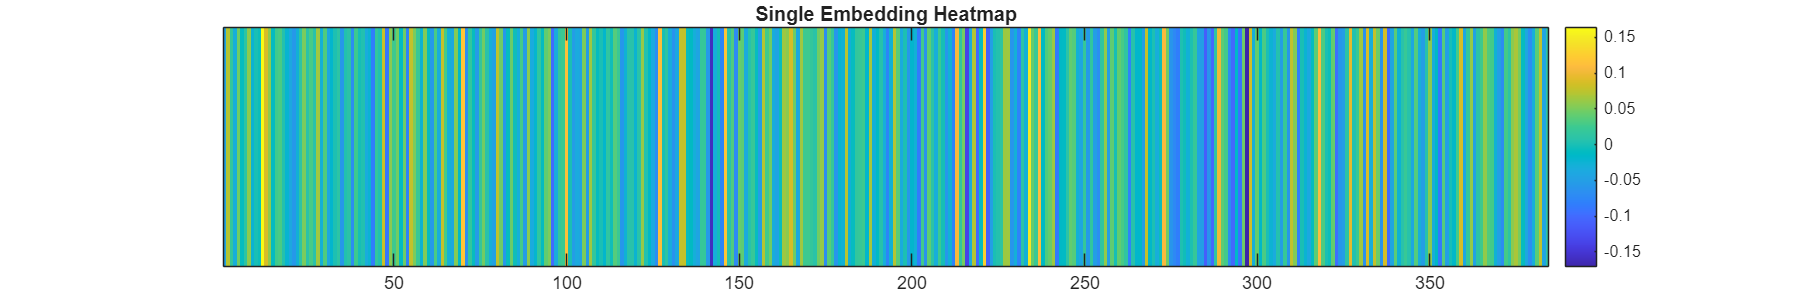

plotSingleEmbedding(embedding1)

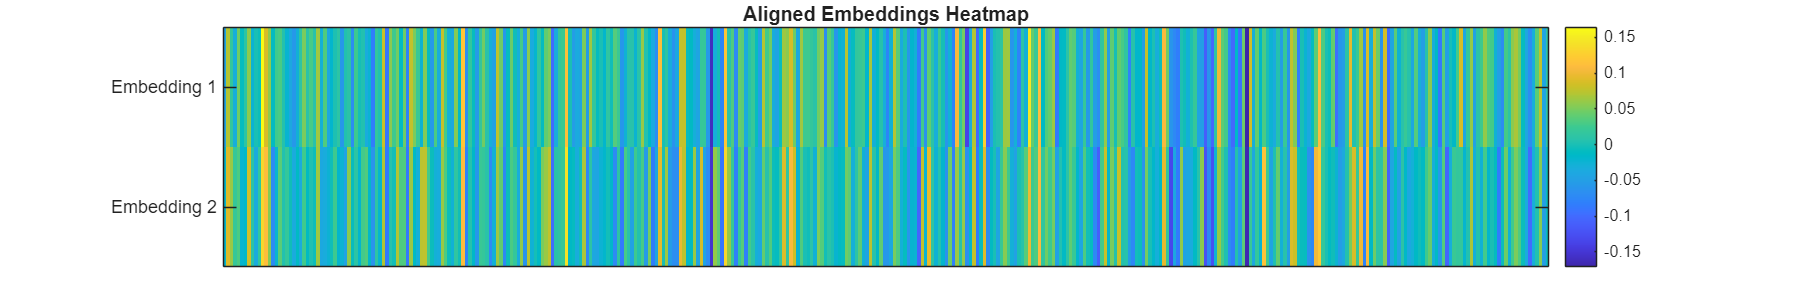

embedding2 = model.embed(sentences(2));
plotAlignedEmbeddings(embedding1, embedding2)

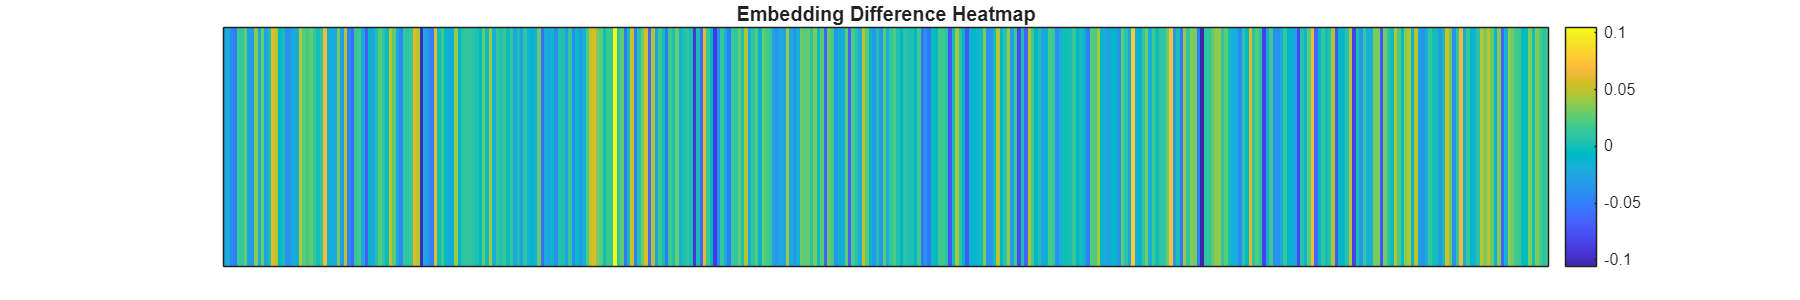

plotDifferenceEmbeddings(embedding1,embedding2)

Process the whole paragraph in one call

embeddings = model.embed(sentences)

embeddings =    -0.0452    0.0716    0.0172   -0.0316    0.0476   -0.0080    0.0121    0.0578   -0.0236    0.0006   -0.0058    0.1645    0.0872    0.0575   -0.0096    0.0257    0.0318    0.0048   -0.0224   -0.0381   -0.0567   -0.0271    0.0124    0.0493    0.0092    0.0300    0.0072    0.0636   -0.0289    0.0344   -0.0391   -0.0202    0.0009    0.0116   -0.0567    0.0033    0.0108   -0.0678    0.0246   -0.0009    0.0038   -0.0342   -0.0243   -0.0845    0.0169    0.0033    0.0806   -0.0888    0.0559    0.0244
   -0.0179    0.0900    0.0614    0.0197    0.0309   -0.0213   -0.0139    0.0841    0.0107   -0.0358    0.0154    0.1339    0.1108    0.0546   -0.0694   -0.0224    0.0375    0.0035    0.0180   -0.0036   -0.0355   -0.0124   -0.0353    0.0255   -0.0102    0.0027   -0.0059    0.0635   -0.0383   -0.0343   -0.0256   -0.0044    0.0252   -0.0202   -0.0247   -0.0452    0.0569   -0.0063    0.0123   -0.0201    0.0279    0.0338   -0.0167   -0.0620    0.0128   -0.0207    0.0707   -0.0854    0.

### Vector Search

% Find the closest to a new sentence
query_sentence = "good times";
query_embedding = model.embed(query_sentence);
distance = cosineSimilarity(query_embedding,embeddings)

distance =     0.6778    0.5655    0.1804    0.1735    0.1918    0.1941    0.2153    0.1729    0.2941    0.1864    0.2953    0.2735    0.2134    0.1723    0.2245    0.0154    0.2857    0.0846


[B,I] = sort(distance,"descend")

B =     0.6778    0.5655    0.2953    0.2941    0.2857    0.2735    0.2245    0.2153    0.2134    0.1941    0.1918    0.1864    0.1804    0.1735    0.1729    0.1723    0.0846    0.0154


I =      1     2    11     9    17    12    15     7    13     6     5    10     3     4     8    14    18    16


s = sentences(I); s(B>0.5)

ans = 2×1 string array
    "It was the best of times"
    "it was the worst of times"


Let's use Facebook AI Similarity Search (FAISS)

d = py.int(384); % Dimension of the embeddings
index = py.faiss.IndexFlatL2(d);
index.add(embeddings)

% Save the index to a file
py.faiss.write_index(index, "charles.index");

% Later, load the index from the file
index = py.faiss.read_index("charles.index");

% Encode the sentence "good times"
query_sentence = "good times";
query_embedding = model.embed(query_sentence);

% Convert query_embedding to a numpy array and reshape to [1, 384]
query_embedding = py.numpy.reshape(query_embedding, py.tuple({py.int(1), d}));

k = py.int(5);  % Number of nearest neighbors to retrieve
res = index.search(query_embedding, k);
distance = double(res{1})

distance =     0.6443    0.8690    1.4095    1.4118    1.4287


indices = int64(res{2})

indices = 1×5 int64 row vector
    0    1   10    8   16


disp("Nearest neighbors (smaller is better):")

Nearest neighbors (smaller is better):


% Loop over the number of neighbors returned.
% Note: FAISS returns 0-indexed indices, so add 1 for MATLAB indexing.
for i = 1:size(indices, 2)
    idx = indices(1, i) + 1;  
    % Use either sentences{idx} (if sentences is a cell array)
    % or sentences(idx) (if sentences is a string array)
    fprintf("Sentence: %s, Distance: %f\n", sentences{idx}, distance(1, i));
end

Sentence: It was the best of times, Distance: 0.644333
Sentence: it was the worst of times, Distance: 0.868980
Sentence: we had everything before us, Distance: 1.409483
Sentence: it was the spring of hope, Distance: 1.411791
Sentence: for good or for evil, Distance: 1.428674


### Utils

Function to visualize a single embedding as a heatmap

function plotSingleEmbedding(embedding)
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(embedding);
    
    % Set a colormap 
    colormap("parula");
    
    % Remove y-axis ticks
    set(gca, 'YTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Single Embedding Heatmap');
end

Function to plot embeddings aligned

function plotAlignedEmbeddings(embedding1, embedding2)
    % Stack the embeddings for aligned visualization 
    % (each embedding is assumed to be a row vector)
    aligned_embeddings = [embedding1; embedding2];
    
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(aligned_embeddings);
    
    % Set colormap
    colormap("parula");
    
    % Set the y-axis ticks to correspond to the two embeddings
    set(gca, 'YTick', [1, 2], 'YTickLabel', {'Embedding 1', 'Embedding 2'});
    
    % Remove x-axis ticks
    set(gca, 'XTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Aligned Embeddings Heatmap');
end

Function to compare one embedding over another

function plotDifferenceEmbeddings(embedding1, embedding2)
    % Compute the difference between the embeddings
    difference = embedding1 - embedding2;
    
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(difference);
    
    % Set colormap 
    colormap(parula);
    
    % Remove x-axis and y-axis ticks for cleaner visualization
    set(gca, 'XTick', []);
    set(gca, 'YTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Embedding Difference Heatmap');
end